## The Nyquist–Shannon Sampling Theorem and Aliasing

We state the Nyquist-Shannon sampling theorem and observe an example. This is basically concerned with one-variable integrable functions whose Fourier transforms are compactly supported. Such functions are automatically real analytic and can be extended to entire functions on $\mathbb{C}$. We employ the definition of Fourier transform as follows. For an appropriate one-variable function $f(x)$, its Fourier transform is defined by 


$$\hat{f}(\xi)
:=
\frac{1}{\sqrt{2\pi}}
\int_{-\infty}^\infty
e^{-ix\xi}
f(x)
dx,
\quad
\xi\in\mathbb{R}.$$


We use the normalized sinc function defined by 


$$\text{sinc}(x)
:=
\frac{\sin(\pi x)}{\pi x}
\quad
(x\ne0),
\quad
\text{sinc}(0):=1.
$$


### The Nyquist-Shannon sampling theorem

Let $B>0$. Suppose that $f(x)$ is an integrable smooth functions on $\mathbb{R}$ and $\hat{f}(\xi)=0$ for $|\xi| \geq B$. Then for any $s \in (0,\pi/B]$, we have 


$$f(x)
=
\sum_{n=-\infty}^\infty
f(sn)
\cdot
\text{sinc}\left(\frac{x}{s}-n\right),$$



$$\int_{-\infty}^\infty
|f(x)|^2
dx
=
s
\sum_{-\infty}^\infty
|f(sn)|^2.$$


The parameter $s>0$ is said to be the sampling period. 

### Observation: sampling and aliasing

Let $f(x)$ be a function defined by 


$$f(x):=\frac{2\bigl(1-\cos(\pi x)\bigr)}{(\pi x)^2}
\quad 
(x\ne0),
\qquad
f(0):=1.$$


Then 


$$\hat{f}(\xi)
=
\frac{\sqrt{2}(\pi-|\xi|)}{\pi^{3/2}}
\quad
(|\xi|\leq\pi),
\quad
\hat{f}(\xi)=0
\quad
(|\xi|>\pi).$$


If we set 


$$F(x;s)
:=
\sum_{-\infty}^\infty
f(sn)
\cdot 
\text{sinc}\left(\frac{x}{s}-n\right),
\quad
s>0,$$


then the Nyquist–Shannon Sampling Theorem implies that 

- 
$$f(\cdot)=F(\cdot;s),
\quad
s\in(0,1], $$


- 
$$f(\cdot){\ne}F(\cdot;s),
\quad
s>1. $$


The latter one is said to be aliasing. 

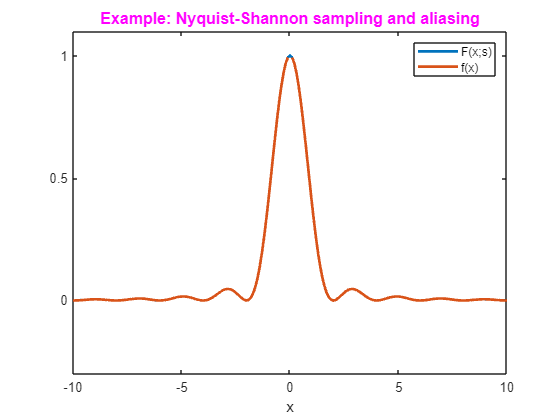

x = linspace(-10,10,201);

s =0.5;

F=sinc(x/s);
if (x==0)
   f=1;
else
   f=2*power(pi*x,-2).*(1-cos(pi*x));
end

for n=1:20
    a=2*power(pi*n*s,-2)*(1-cos(pi*n*s));
    b=sinc(x/s-n);
    c=sinc(x/s+n);
    F=F+a*b+a*c;
end

plot(x,F,x,f,'LineWidth',2)
     title('Example: Nyquist-Shannon sampling and aliasing','Color','magenta','FontSize',12)
     ylim([-0.3,1.1])
     xlabel("x")
     xticks([-10 -5 0 5 10])
     xticklabels({'-10','-5','0','5','10'})
     yticks([0 0.5 1])
     yticklabels({'0','0.5','1'})
    legend('F(x;s)','f(x)','Location','northeast')